# Workspace comparision

clc;
clear;

Linear = load("Linear_sigmoid_25.mat");
SAM    = load("Sam_sigmoid_25.mat");

## plot out accuracy

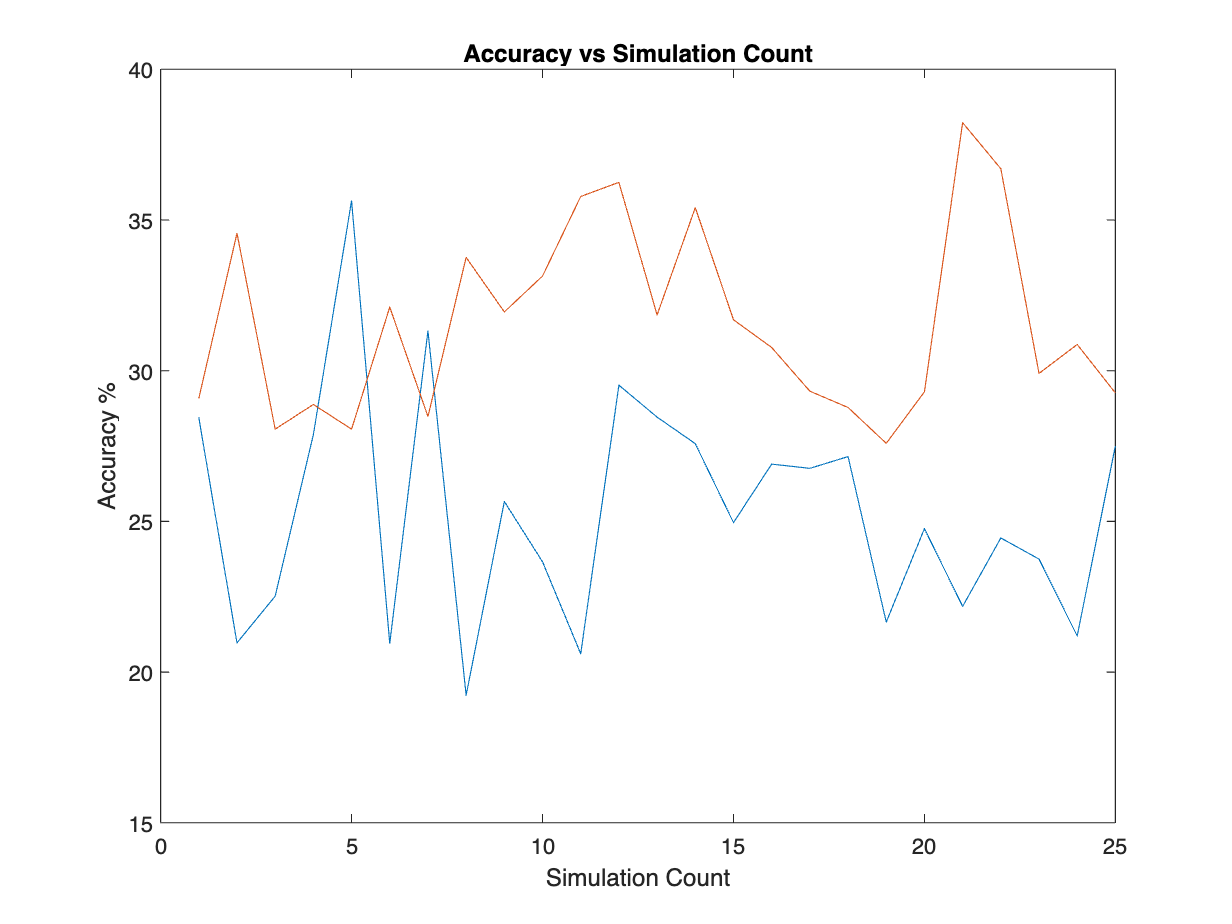

Y1 = Linear.acc;
Y2 = SAM.acc;

figure;
plot(1:25,[100*Y1,100*Y2]);
title("Accuracy vs Simulation Count");
xlabel("Simulation Count");
ylabel("Accuracy %");

## display relevant statistics

Y1_avg = Linear.avg_accuracy;
Y1_std = Linear.sdv_accuracy;
Y1_var = Linear.var_accuracy;
Y1_min = min(Y1);
Y1_max = max(Y1);

Y2_avg = SAM.avg_accuracy;
Y2_std = SAM.sdv_accuracy;
Y2_var = SAM.var_accuracy;
Y2_min = min(Y2);
Y2_max = max(Y2);

tb_labels   = ["Linear";"SAM"];
tb_average  = [Y1_avg;Y2_avg];
tb_stddev   = [Y1_std;Y2_std];
tb_variance = [Y1_var;Y2_var];
tb_minimum  = [Y1_min;Y2_min];
tb_maximum  = [Y1_max;Y2_max];
tb_vars     = ["Function";"Mean";"Standard Deviation";"Variance";"Minimum";"Maximum"];
tb = table(tb_labels,tb_average,tb_stddev,tb_variance,tb_minimum,tb_maximum,VariableNames=tb_vars);
disp(tb);

    Function     Mean      Standard Deviation     Variance     Minimum    Maximum
    ________    _______    __________________    __________    _______    _______

    "Linear"    0.25349         0.038517          0.0014835    0.1923     0.3564 
    "SAM"       0.31592         0.031121         0.00096854    0.2759     0.3823 

